# Fourier Analysis 

# Shahriar Attar 810100186

## Part 1 Matlab Basics

### 1.1 Plotting functions

First we want to learn how to plot different functions in matlab 

- 
$$y = cot(\frac{\pi t}{4})sin(\frac{\pi t}{8})$$
 

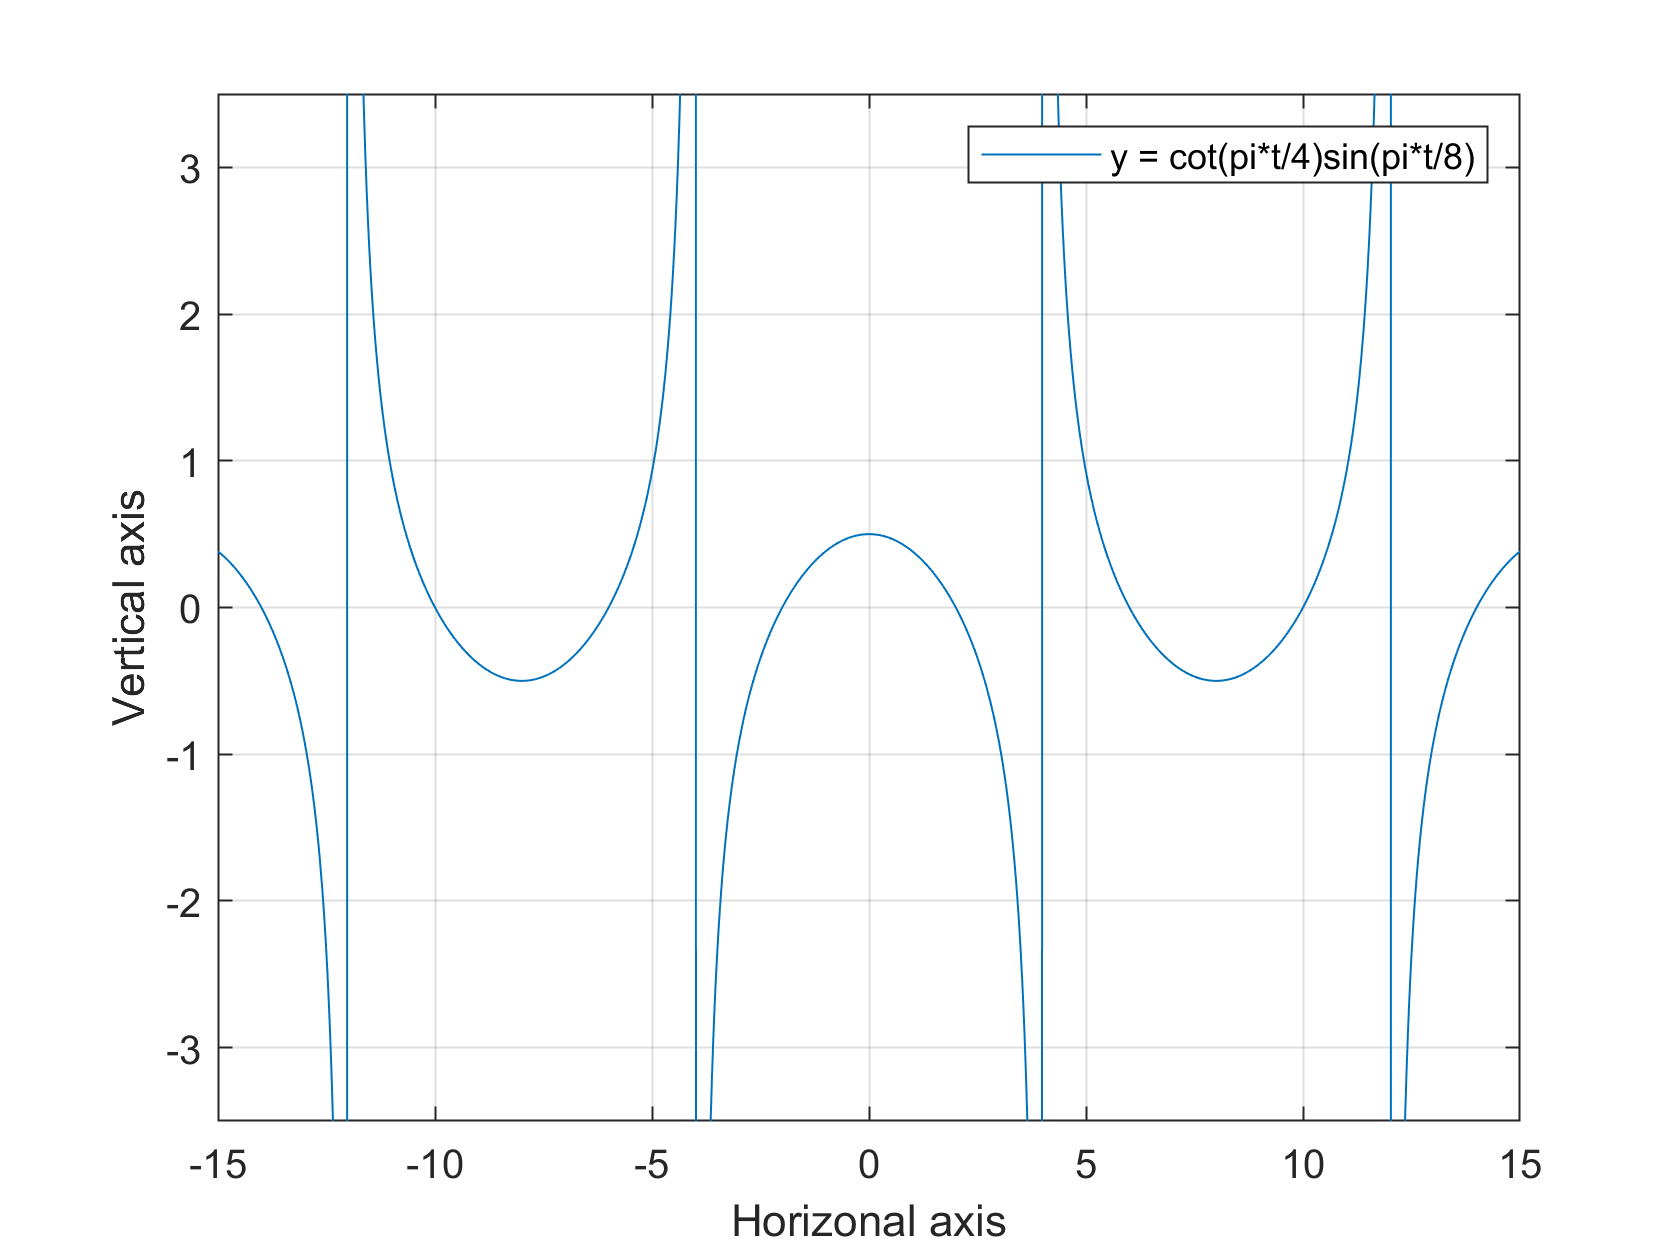

t_min = -15;
t_max = 15;
t = linspace(t_min, t_max, 1000);
x = cot(pi*t/4) .* sin(pi*t/8);
plot(t, x)
xlabel("Horizonal axis");
ylabel("Vertical axis");
ylim([-3.5 3.5]);
xlim([t_min t_max]);
legend("y = cot(pi*t/4)sin(pi*t/8)")
grid on;

- 
$$y = sgn(1/t^2)
$$


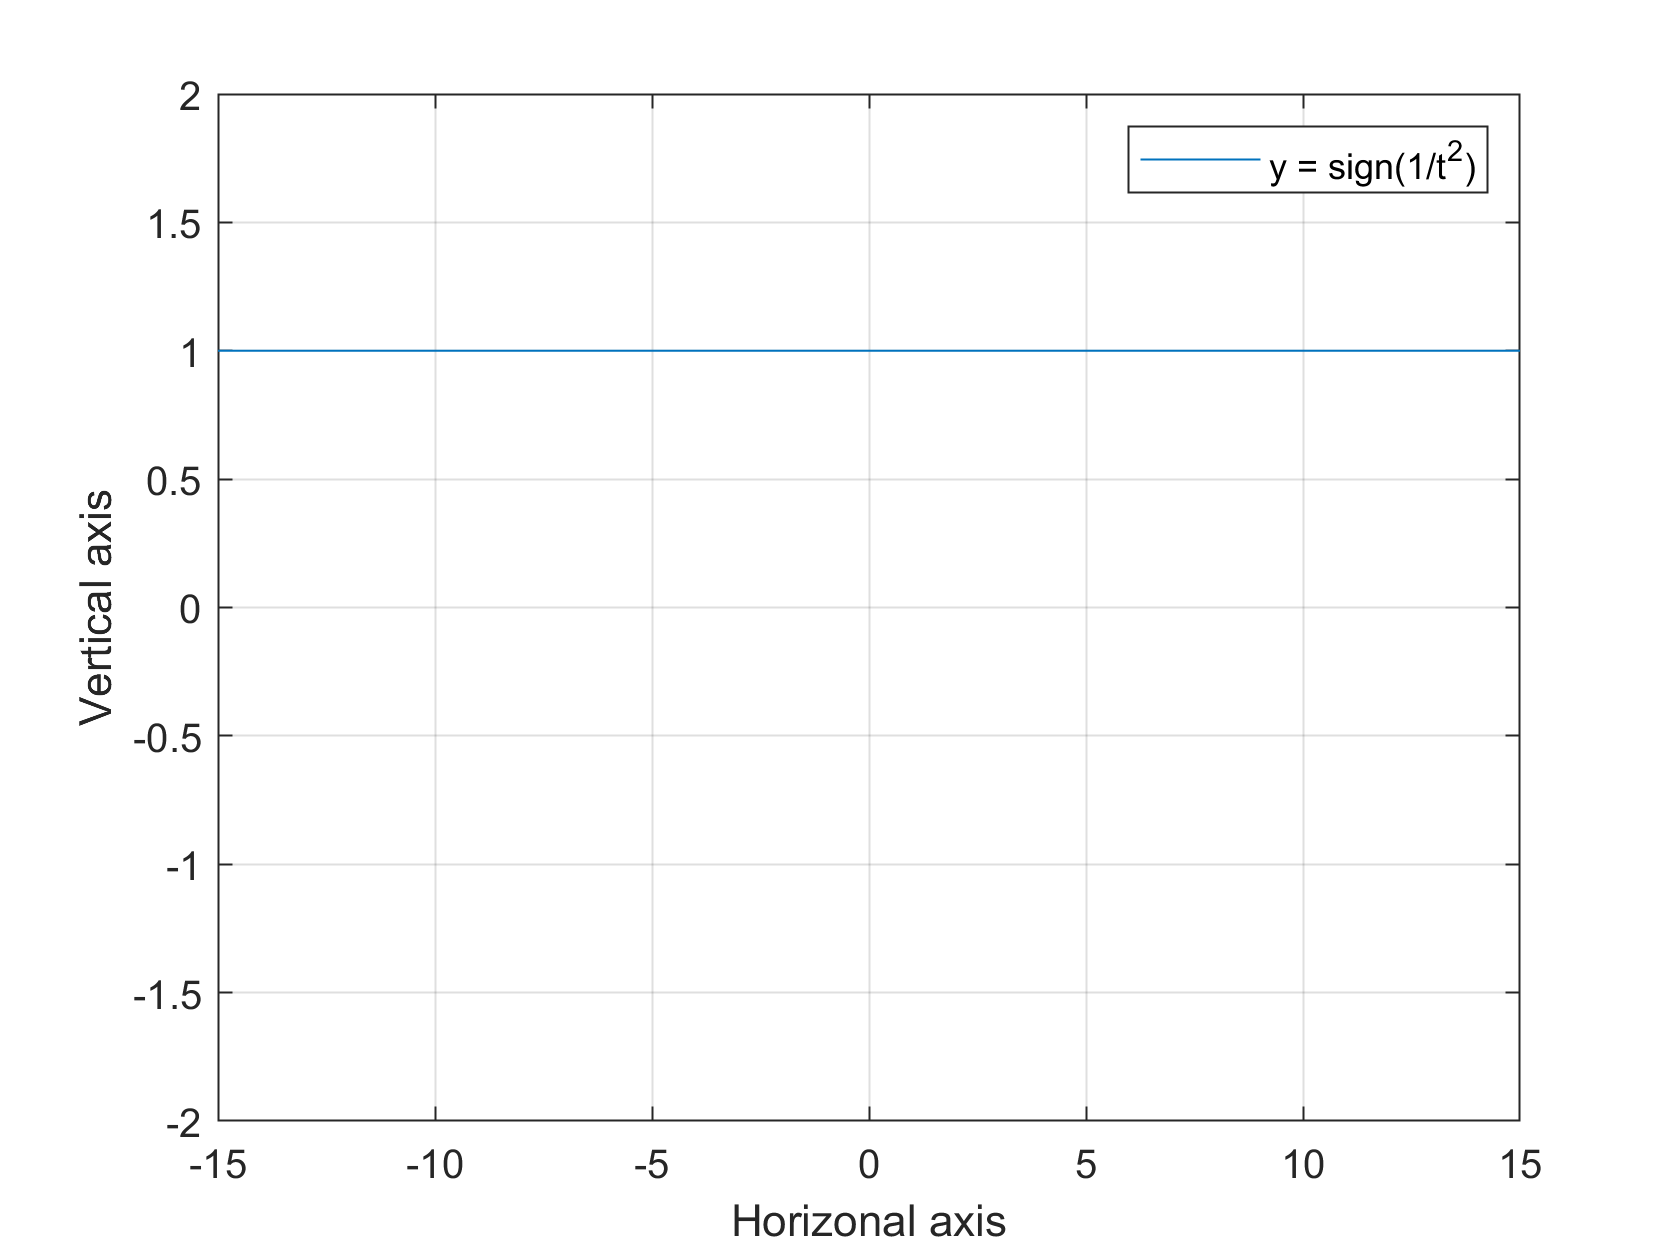

x = sign(1./t.^2);
plot(t, x)
xlabel("Horizonal axis");
ylabel("Vertical axis");
ylim([-2 2]);
xlim([t_min t_max]);
legend("y = sign(1/t^2)")
grid on;

- plotting$\[
y =
\begin{cases}
-1 & \text t \lt -3\\
3ramp(t) & \text{-3 < t < 3}\\
e^{-2.5t} & \text{ t > 3}
\end{cases}
\]$

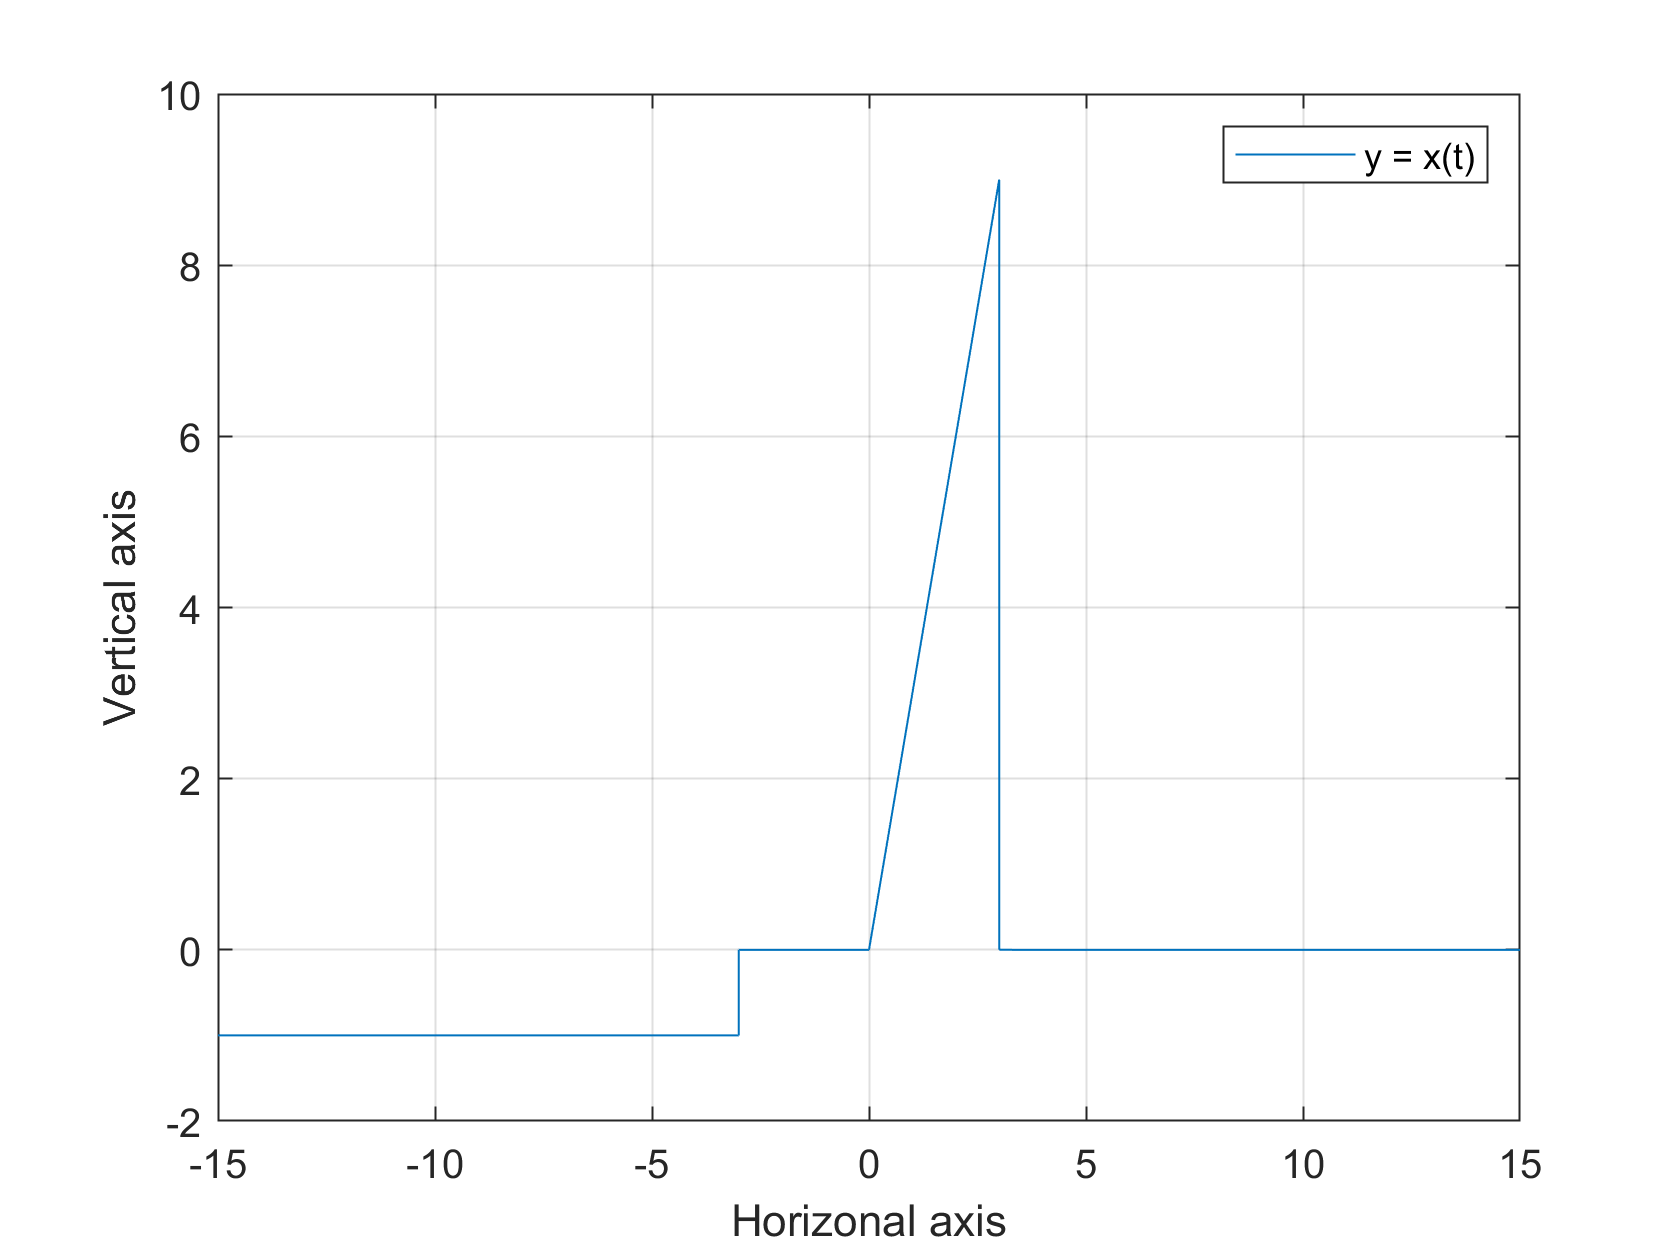

first_t = linspace(t_min, -3, 1000);
first_x = first_t ./ -first_t;
second_t = linspace(-3, 3, 1000);
second_x = 3 * max(0, second_t);
third_t = linspace(3, t_max, 1000);
third_x = exp(-2.5 * third_t);
t = [first_t second_t third_t];
x = [first_x second_x third_x];
plot(t, x)
xlabel("Horizonal axis");
ylabel("Vertical axis");
ylim([-2 10]);
xlim([t_min t_max]);
legend("y = x(t)")
grid on;

## Part 2. Fourier Series

### 2.1 Fourier series of f(x) = $x^\alpha$

The corresponding functions are at the end

fourier_series has 4 parameters(Num, P, alpha, Nshow) and show the fourier series of $x^\alpha$(until n = Nshow)  and plot it until n = Num and p is number of periods we have to show.

### 2.2 Calculating the Fourier series 

the given equation is not of the form of the previous function so it cannot be used! but to show the performance we plot x^5.

$$to\_show(x) = \frac{\sin\left(x\right)\,\left(240\,\pi -40\,\pi^{3}+2\,\pi^{5}\right)}{\pi }-\frac{\sin\left(2\,x\right)\,\left(\frac{15\,\pi }{2}-5\,\pi^{3}+\pi^{5}\right)}{\pi }-\frac{\sin\left(4\,x\right)\,\left(\frac{15\,\pi }{64}-\frac{5\,\pi^{3}}{8}+\frac{\pi^{5}}{2}\right)}{\pi }-\frac{\sin\left(6\,x\right)\,\left(\frac{5\,\pi }{162}-\frac{5\,\pi^{3}}{27}+\frac{\pi^{5}}{3}\right)}{\pi }+\frac{\sin\left(3\,x\right)\,\left(\frac{80\,\pi }{81}-\frac{40\,\pi^{3}}{27}+\frac{2\,\pi^{5}}{3}\right)}{\pi }+\frac{\sin\left(5\,x\right)\,\left(\frac{48\,\pi }{625}-\frac{8\,\pi^{3}}{25}+\frac{2\,\pi^{5}}{5}\right)}{\pi }$$

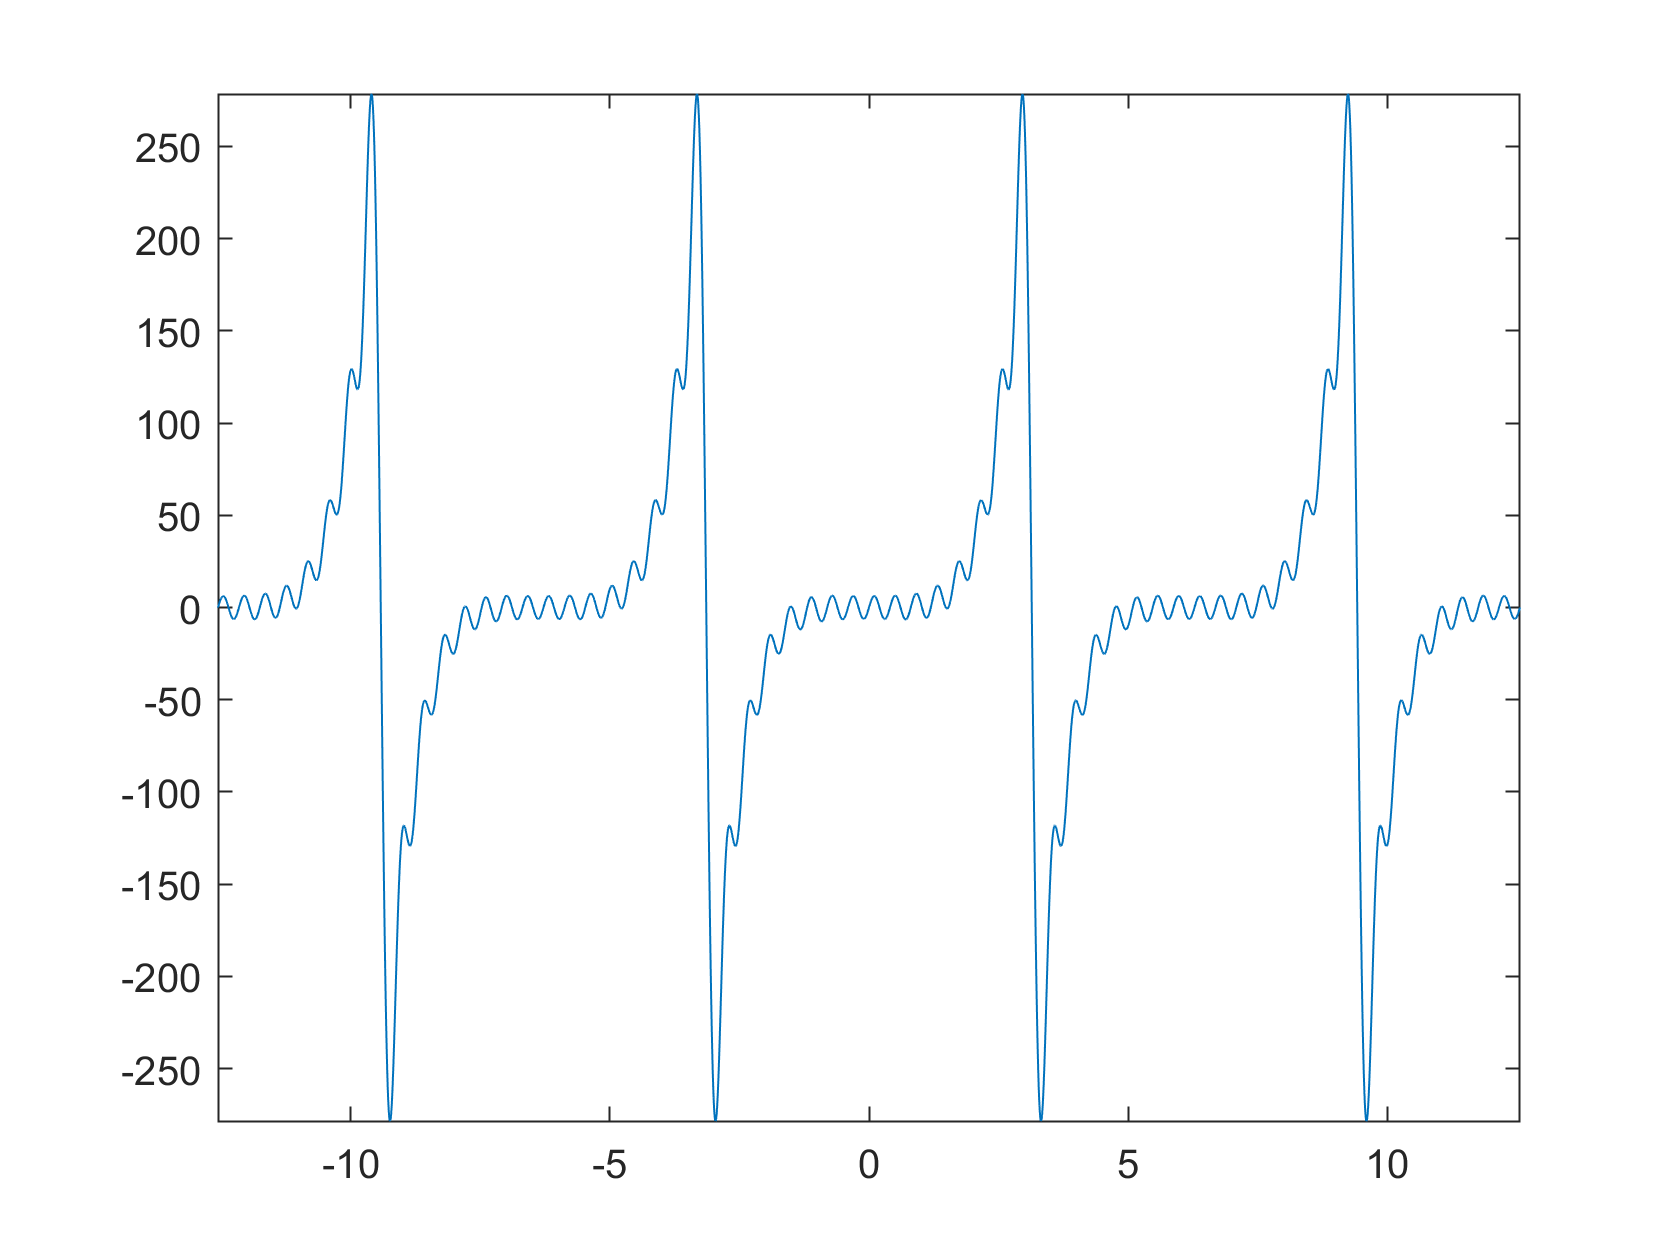

fourier_series(15, 4, 5, 6);

### 2.3 Plotting Fourier Series with Different Nums and Comparison

In general the bigger Num the closer our plot will be a better approximation, and we can we that is our plots as well.

fourier_series(1, 3, 2, 5);

$$to\_show(x) = \cos\left(2\,x\right)-\frac{4\,\cos\left(3\,x\right)}{9}+\frac{\cos\left(4\,x\right)}{4}-\frac{4\,\cos\left(5\,x\right)}{25}-4\,\cos\left(x\right)+\frac{\pi^{2}}{3}$$

hold on;
fourier_series(10, 3, 2, 5);

$$to\_show(x) = \cos\left(2\,x\right)-\frac{4\,\cos\left(3\,x\right)}{9}+\frac{\cos\left(4\,x\right)}{4}-\frac{4\,\cos\left(5\,x\right)}{25}-4\,\cos\left(x\right)+\frac{\pi^{2}}{3}$$

hold on;
fourier_series(50, 3, 2, 5);

$$to\_show(x) = \cos\left(2\,x\right)-\frac{4\,\cos\left(3\,x\right)}{9}+\frac{\cos\left(4\,x\right)}{4}-\frac{4\,\cos\left(5\,x\right)}{25}-4\,\cos\left(x\right)+\frac{\pi^{2}}{3}$$

fourier_series(100, 3, 2, 5);

$$to\_show(x) = \cos\left(2\,x\right)-\frac{4\,\cos\left(3\,x\right)}{9}+\frac{\cos\left(4\,x\right)}{4}-\frac{4\,\cos\left(5\,x\right)}{25}-4\,\cos\left(x\right)+\frac{\pi^{2}}{3}$$

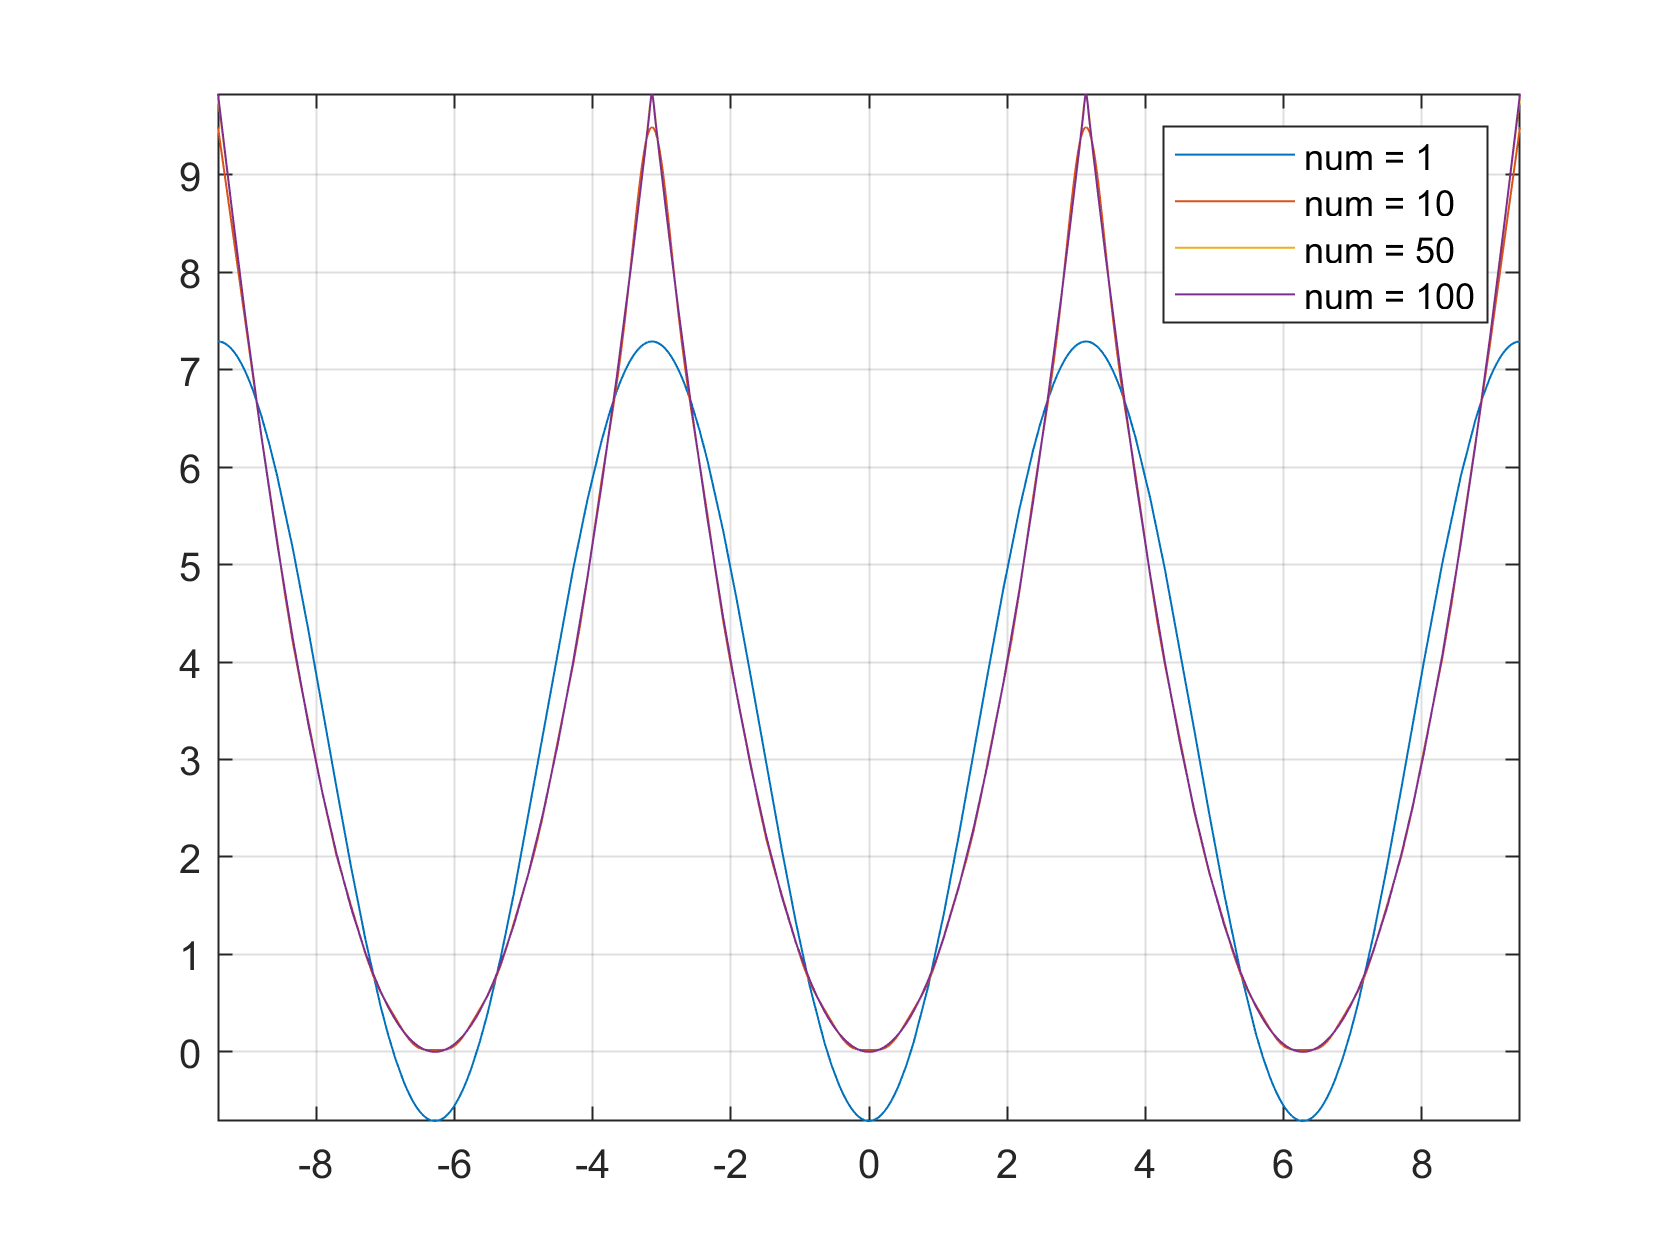

legend("num = 1", "num = 10", "num = 50", "num = 100");
grid on;
hold off;

### 2.4 Calculating the limit of a series' sum

Since $x^2$ is an even function, its Fourier series will only have cosine terms:


$$\[
x^2 = \frac{a_0}{2} + \sum_{n=1}^{\infty} a_n \cos(nx)
\]$$



$$\[
a_0 = \frac{1}{2\pi} \int_{-\pi}^{\pi} x^2 dx = \frac{\pi^2}{3}
\]
$$



$$\[
a_n = \frac{1}{\pi} \int_{-\pi}^{\pi} x^2 \cos(nx) dx = \frac{4}{\pi} \int_{0}^{\pi} x^2 \cos(nx) dx
\]$$


and


$$
\int x^2 \cos(nx) dx = \frac{x^2}{n} \sin(nx) - \frac{2}{n} \int x \sin(nx) dx 
= \frac{x^2}{n} \sin(nx) + \frac{2}{n^2} \cos(nx) - \frac{2x}{n^2} \cos(nx) 
= \frac{x^2}{n} \sin(nx) - \frac{2}{n^3} \sin(nx) - \frac{2}{n^2} x \cos(nx)
$$


so


$$a_n = \frac{2}{\pi} \int_{0}^{\pi} x^2 \cos(nx) dx 
= \frac{2}{\pi} \left[ \frac{x^2}{n} \sin(nx) - \frac{2}{n^2} \sin(nx) - \frac{2}{n^2} x \cos(nx) \right]_{0}^{\pi} 
= \frac{4}{n^2} (-1)^n$$
    


$$\[
x^2 = \frac{\pi^2}{3} + \sum_{n=1}^{\infty} \frac{4}{n^2} (-1)^n \cos(nx)
\]$$


Now we have to show$\sum_{n=1}^{\infty} \frac{1}{n^2} 
= \frac{\pi^2}{6}$. we set $x = \pi:$


$$\pi^2= \frac{\pi^2}{3} + 4\sum_{n=1}^{\infty} \frac{1}{n^2} $$


so


$$ \sum_{n=1}^{\infty} \frac{1}{n^2} = \frac{\pi^2}{6}  $$


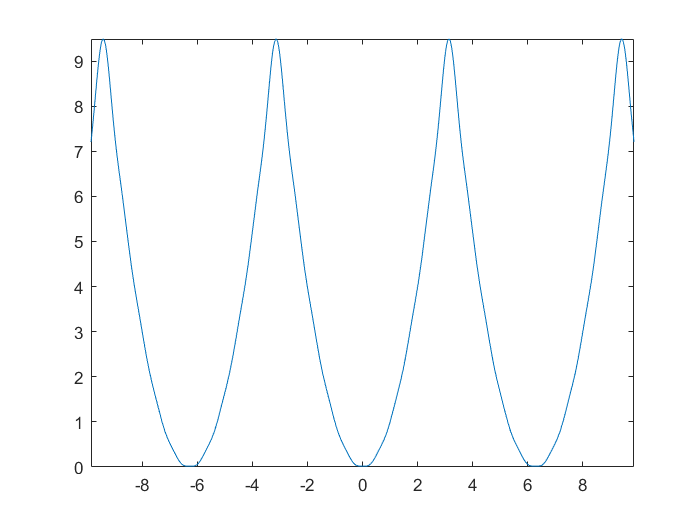

[to_show] = fourier_series(10, pi, 2, 100);

syms x;
sigma(x) = (to_show(x) - pi^2/3) / 4;
difference = vpa(sigma(pi) - pi^2/6, 5);
fprintf("The difference between pi^2/6 and the approximate sum: %f", difference);

The difference between pi^2/6 and the approximate sum: -0.009950

### 2.5 Harmonic Analysis in Fourier Series


$$f(x)= \frac{A_0}{2}+ \sum_{n=1}^{\infty}{A_ncos(nx)+B_nSin(nx)} \\
A_0 = 2 \frac{\sum f(x)}{numOfSamples}, 
A_n = 2 \frac{\sum f(x)cos(nx)}{n},
B_n = 2 \frac{\sum f(x)sin(nx)}{n}


$$


#### 2.5.1 Harmonic Analysis Simulation

first_n_harmonic gets values of x ,f(x) and n, calculates the first n harmonics of Fourier Series and plot it. 

With given table I called the function:

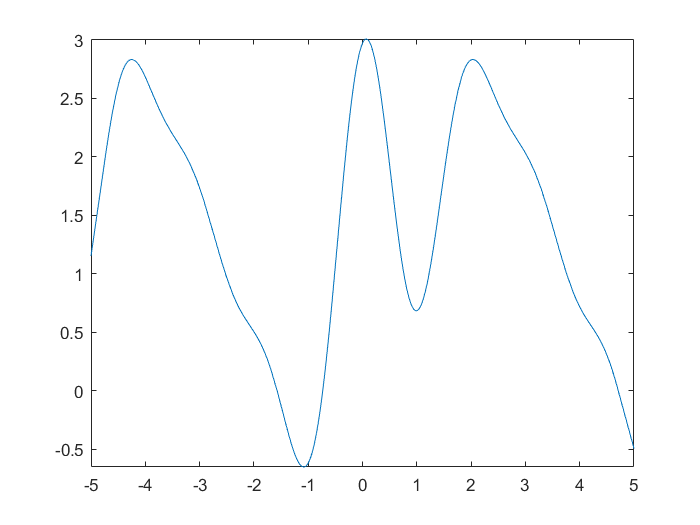

$$fourier\_func = 0.7\,\cos\left(2.0\,x\right)+0.35\,\cos\left(4.0\,x\right)-0.17321\,\sin\left(2.0\,x\right)+0.086603\,\sin\left(4.0\,x\right)+0.73333\,\cos\left(3.0\,x\right)-2.6942e-16\,\sin\left(3.0\,x\right)-0.2\,\cos\left(x\right)+1.0392\,\sin\left(x\right)+1.3857$$

xs = [0 pi/3 2*pi/3 pi 4*pi/3 5*pi/3 2*pi];
fx = [1 1.4 1.9 1.7 1.5 1.2 1];
first_n_harmonic(xs, fx, 4);

## Part 3 Fourier Transform

### 3.2 Checking some functions in terms of time and frequency

plot_and_fftshift gets a function and plot it and then calculates its Fourier Transform and plots it too. I used fft and fftshift functions to calculate the Fourier Transform.

*Why should we use fftshift?*

when you use fft the array will be:

0 1 2 3 ... Fs/2   -Fs/2 ... -3 -2 -1

  positive freq        negative freq

by using fftshift zero frequncy is shifted to center of array so we have:

 -Fs/2 ... -3 -2 -1   0 1 2 3 ... Fs/2

    negative freq      positive freq

### 
$$y = cos(\pi t)$$


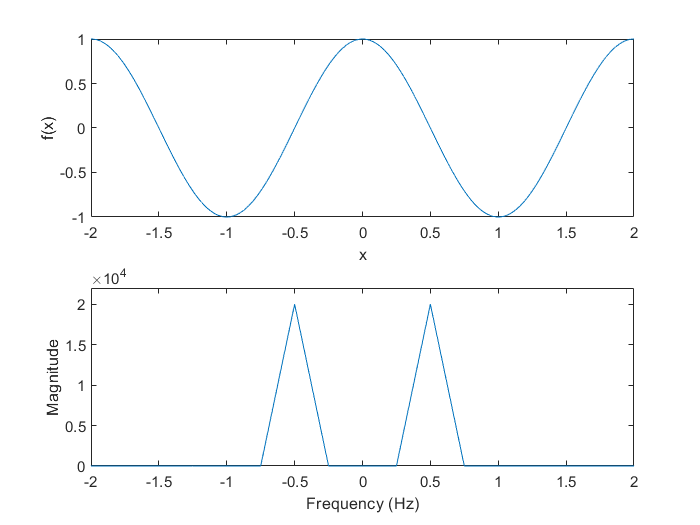

first_t = @(x) cos(pi*x);
plot_and_fftshift(first_t, -2, 2, 10000);

The output is two delta dirac at -0.5 and 0.5 and theoretically.:


$$F(\omega) = \int_{-\infty}^{\infty} \cos(\pi t) e^{-j\omega t} dt$$



$$\Longrightarrow F(\omega) = \int_{-\infty}^{\infty} \frac{1}{2} \left( e^{j\pi t} + e^{-j\pi t} \right) e^{-j\omega t} dt$$



$$ \Longrightarrow F(\omega) = \frac{1}{2} \int_{-\infty}^{\infty} e^{j(\pi - \omega)t} + e^{-j(\pi + \omega)t} dt$$



$$\Longrightarrow F(\omega) = \pi \left( \delta(\omega - \pi) + \delta(\omega + \pi) \right)$$


which in terms of frequency is:


$$F(f) = \pi \left( \delta(f - \frac{1}{2}) + \delta(f + \frac{1}{2}) \right)
$$


which is like what our function found.

- 
$$y = 1$$


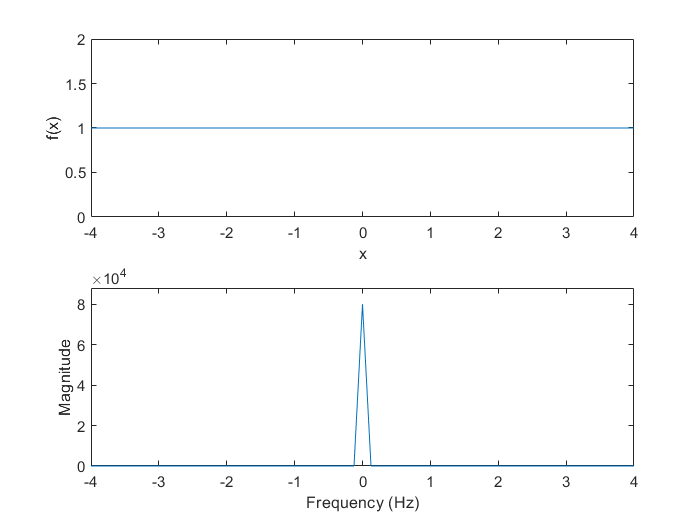

first_t = @(x) x - x + 1;
plot_and_fftshift(first_t, -4, 4, 10000);

The transform of the function is an impulse on f = 0 and theoretically:


$$F(f) = \int_{-\infty}^{\infty} 1 \cdot e^{-2\pi i f t} dt =  2\pi\delta(f)$$


- 
$$y = \delta(t)$$


we defined dirac function as min(1, $\delta(t)$) because the dirac function in MATLAB gets infinite value at 0 and the function didn't work properly with that. With this implemetation f(t) = 0 every but in t = 0. in t = 0 f(t) is 1.

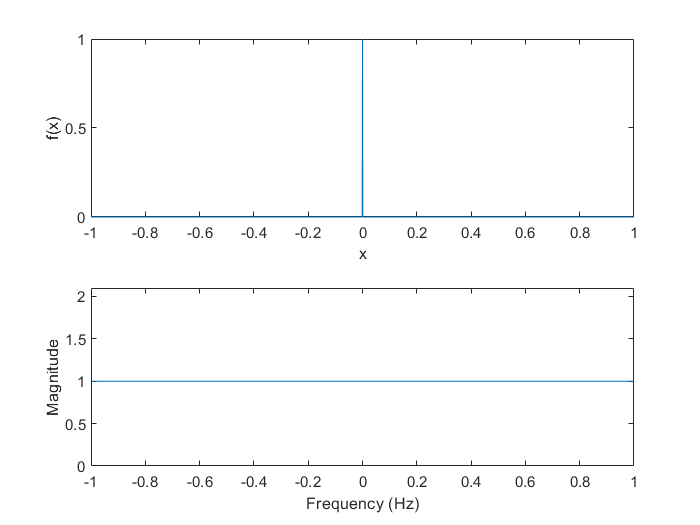

first_t = @(x) min(1, dirac(x));
plot_and_fftshift(first_t, -1, 1, 1000);

according to our function Fourier transform of dirac function is a constant(y = 1) and theoretically:


$$F(f) = \int_{-\infty}^{\infty} \delta(t) \cdot e^{-2\pi i f t} dt = e^{-2\pi i f \times 0} = 1$$


### 3.3 Music

filename = 'ABITW.mp3';
[x, Fs] = audioread(filename);
display(Fs)

Fs = 44100

The Nyquist-Shannon theorem says in order to accurately reconstruct a continuous-time signal from its discrete-time samples, the sampling frequency must be at least twice the highest frequency component in the signal so the Fs in output should be that high.

sound(x, Fs);
pause(length(x)/Fs);
clear sound;

Fs_double = Fs*2;
audiowrite('ABITWDouble.wav', x, Fs_double)

If we play a sound with a sampling rate that is twice the original sampling frequency, the sound will be played back at twice the speed and the pitch of the sound will be higher. This is because the sampling frequency determines the number of samples per second that are used to represent the audio signal.

Fs_half = Fs/2;
audiowrite('ABITWHalf.wav', x, Fs_half)

If we lower the frequency we might go below the minimun frequency stated in The Nyquist-Shannon theorem we might lose some high frequency content in our audio signal. Also If we play a sound with a sampling rate that is half the original sampling frequency, the sound will be played back at half the speed and pitch of the sound will get lower too.

### Functions

function [to_show] = fourier_series(num, p, alpha, nshow)
    syms x;
    y = x ^ alpha;
    syms n;
    l = pi;
    a_0 = int(y, x, -l, l) / l / 2;
    a_n(n) = int(y * cos((n*pi/l) * x), x, -l, l) / l;
    b_n(n) = int(y * sin((n*pi/l) * x), x, -l, l) / l;
    to_show(x) = a_0;
    to_plot(x) = a_0;
    for i=1:nshow
       to_show = to_show + a_n(i) * cos((i*pi/l) * x) + b_n(i) * sin((i*pi/l) * x); 
    end
    for i=1:num
       to_plot = to_plot + a_n(i) * cos((i*pi/l) * x) + b_n(i) * sin((i*pi/l) * x); 
    end
    display(to_show);
    fplot(to_plot);
    xlim([-p*pi, p*pi]);
end

function first_n_harmonic(xs, fx, n)
    a = zeros(1, n);
    b = zeros(1, n);
    input_shape = size(xs);
    num_of_samples = input_shape(2);
    a_0 = 2 * sum(fx) / num_of_samples / 2;
    for i=1:n
        for j=1:num_of_samples
            a(i) = a(i) + fx(j) * cos(i*xs(j)); 
            b(i) = b(i) + fx(j) * sin(i*xs(j)); 
        end
        a(i) = 2 * a(i) / i;
        b(i) = 2 * b(i) / i;
    end
    syms x;
    fourier_func = a_0;
    for i=1:n
        fourier_func = fourier_func + a(i) * cos(i*x) + b(i) * sin(i*x);
    end
    fourier_func = vpa(fourier_func, 5);
    fplot(fourier_func);
    display(fourier_func);
end

function plot_and_fftshift(f, x_min, x_max, fs)
    x = x_min:1/fs:x_max;
    y = f(x);
    subplot(2,1,1);
    plot(x, y);
    xlabel('x');
    ylabel('f(x)');
    F = fft(y);
    F = fftshift(F);
    N = length(x); 
    freq = (-N/2:N/2-1)*fs/N;
    subplot(2,1,2);
    plot(freq, abs(F));
    f_max = max(abs(y));
    F_max = max(abs(F));
    xlim([x_min, x_max]);
    ylim([0, max([f_max, F_max])*1.1 + 1]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
end